% Package orientation: Dedicated held-out test for a separately trained SPSA network.

% TEST_SPSA_GPU_implementation_regression_yacht.mlx
% Load SPSA-trained Yacht Hydrodynamics networks and evaluate the held-out split with the
% same standard test, plotting, diagnostics, and publication-data export
% used by the main GPU test script. This script does not train.

clear; clc;
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);

%% ---------------- Saved SPSA Network ----------------
% The SPSA runner currently creates seed 1 by default. Use [1 2 3] after
% training all three SPSA seeds to obtain multi-seed release statistics.
test_seeds = [1];
diagnostic_seed_index = 1;
test_backend = 'gpu';
[model_files, model_file] = snn_resolve_spsa_model_files( ...
    repo_root, 'regression_yacht', test_seeds, diagnostic_seed_index);
save_diagnostic_files = false;
diag_dir = fullfile(repo_root, 'outputs', 'diagnostics', 'regression_yacht_spsa_test_gpu_primary');
if save_diagnostic_files && exist(diag_dir, 'dir') ~= 7, mkdir(diag_dir); end

%% ---------------- Evaluation Overrides ----------------
opts = struct();
opts.model_files = model_files;
opts.seed_list = test_seeds;
opts.model_file = model_file;
opts.batch_size = 32;

%% ---------------- Run Held-Out Test ----------------
result = snn_primary_api('test_static', 'regression', test_backend, opts);

[SEED AUDIT] Single seed tested; no pairwise network-difference check required.
Saved publication analysis data: C:\Users\kaima\OneDrive - University of Calgary\Neural_networks_bias_learning\Spiking_neural_networks\SE adLIF\For Publication\GitHub_V2_multiple_architectures_working\outputs\publication_analysis\regression_yacht_spsa_gpu_test_analysis_20260721_162108_597.mat


fprintf('Tested SPSA-trained Yacht Hydrodynamics network(s) for seed(s) [%s] with the GPU test backend.\n', num2str(test_seeds));

Tested SPSA-trained Yacht Hydrodynamics network(s) for seed(s) [1] with the GPU test backend.


    Seed      Loss       RMSE     PearsonR
    ____    ________    ______    ________

     1      0.048415    5.1095    0.92146 



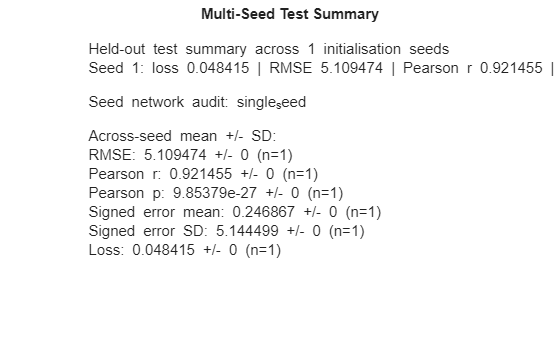

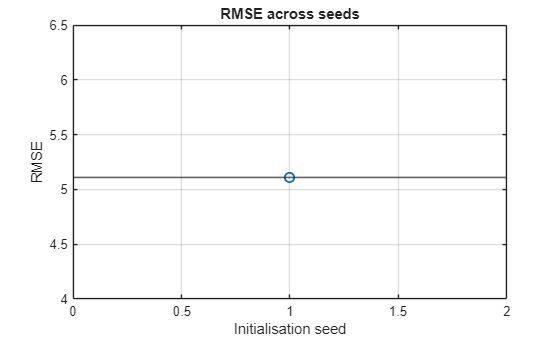

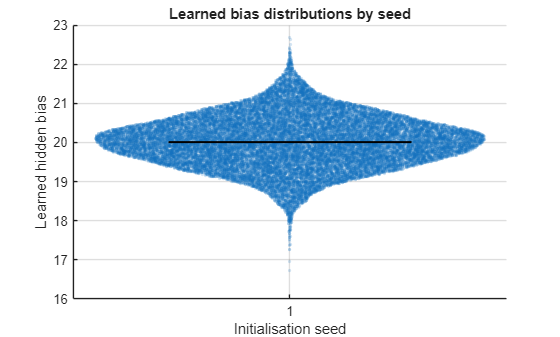

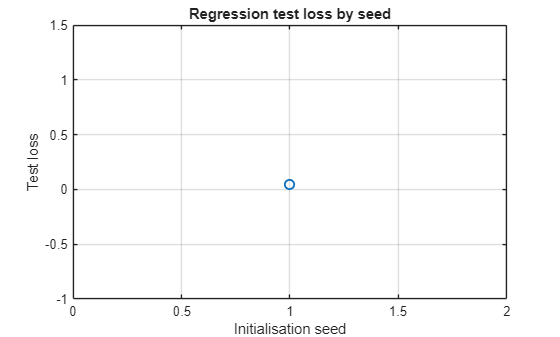

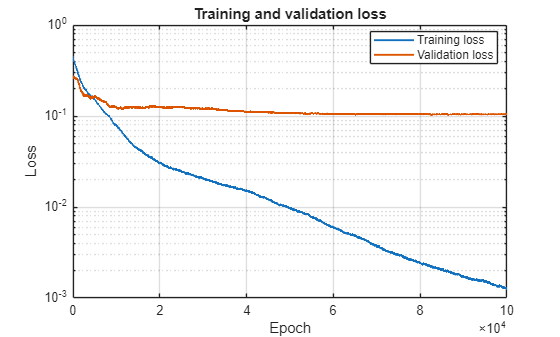

snn_plot_test_result(result);


=== Spiking Diagnostics: yacht_test_regression ===
Samples: 8 | Neurons: 32000 | Steps/sample: 300 | Seconds/sample: 0.3
Mean neuron firing rate: 2.75368 Hz | median 2.5 Hz | 95th percentile 6.25 Hz
Active neurons: 30579 / 32000 (95.56%)
Silent neurons: 1421 / 32000 (4.44%)
Mean population rate by sample: 2.75368 Hz/neuron
Mean active neurons by sample: 47.45% | silent 52.55%
Total within-sample ISIs counted: 90007
Median per-neuron mean inverse-ISI rate: 9.18333 Hz


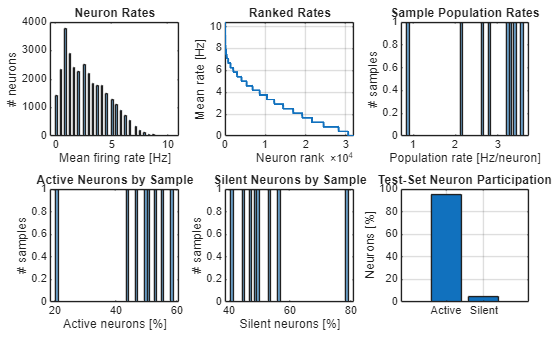

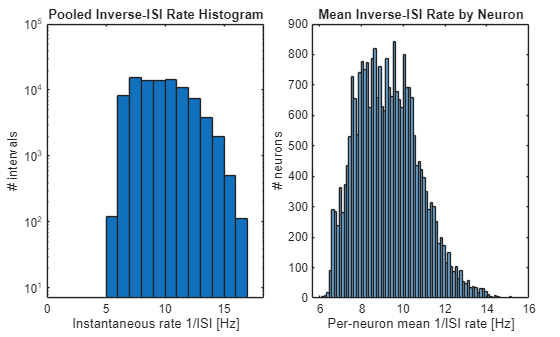

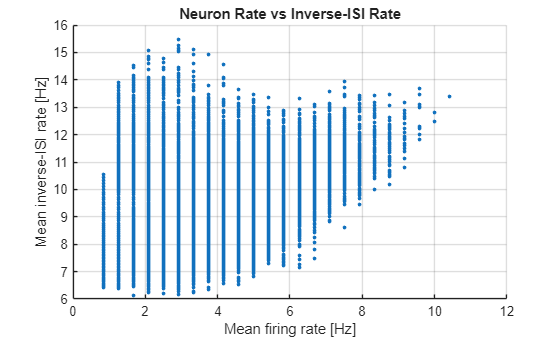

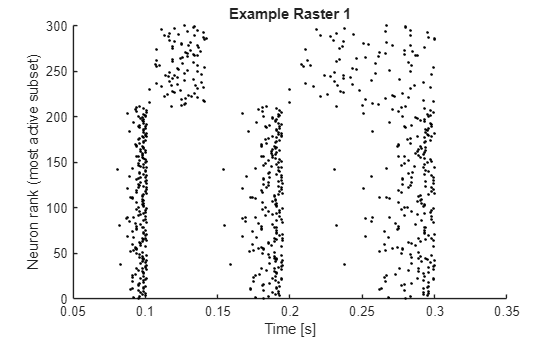

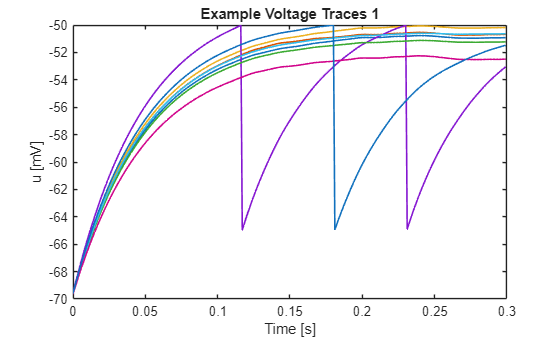

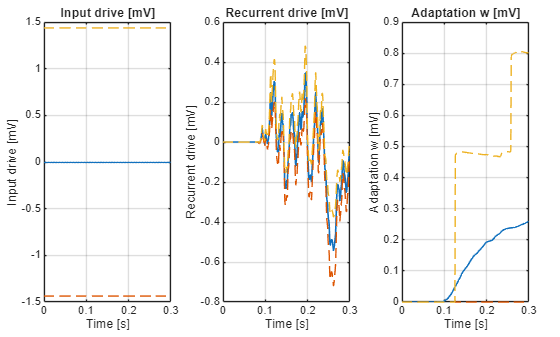

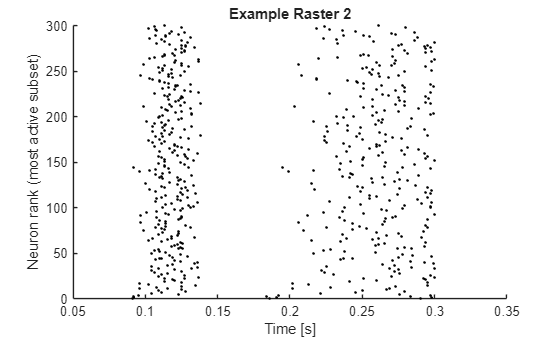

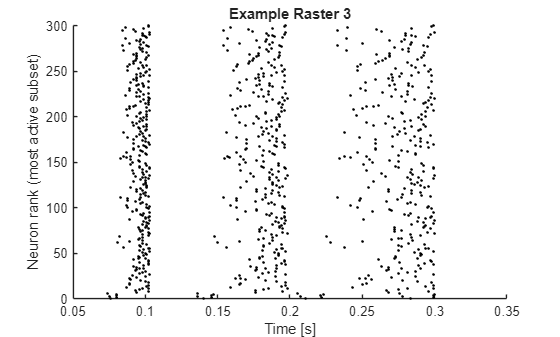

[SPIKING] Displayed spiking diagnostics without saving files. To save files, pass 'save_files', true.



%% ---------------- Spiking Dynamics Diagnostics ----------------
diag_opts = struct();
diag_opts.model_file = model_file;
diag_opts.output_dir = diag_dir;
diag_opts.save_files = save_diagnostic_files;
diag_opts.max_samples = 8;
diag = snn_primary_api('spike_diagnostics_static', 'regression', 'cpu', diag_opts);

fprintf('Test spiking active neurons: %.2f%%%% (%d/%d); silent neurons: %.2f%%%% (%d/%d).\n', ...
    diag.active_neuron_percent, diag.active_neuron_count, diag.n_neurons, ...
    diag.silent_neuron_percent, diag.silent_neuron_count, diag.n_neurons);

Test spiking active neurons: 95.56%% (30579/32000); silent neurons: 4.44%% (1421/32000).


fprintf('Mean per-sample active neurons: %.2f%%%%; silent neurons: %.2f%%%%.\n', ...
    mean(diag.active_percent_by_sample), mean(diag.silent_percent_by_sample));

Mean per-sample active neurons: 47.45%%; silent neurons: 52.55%%.


fprintf('Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.\n');

Displayed test plots and spiking diagnostics inline. Set save_diagnostic_files=true to write diagnostics to disk.


disp(result.test);

          loss: 0.0484
        metric: 0.9215
         count: 63
             Z: [-0.5823 -0.3304 -0.7911 -0.5182 -0.6404 -0.5904 -0.5159 -0.6925 -0.7463 1.5321 -0.6573 0.9790 0.8366 0.3841 -0.7010 1.0882 -0.7659 0.4246 -0.5793 -0.5056 -0.7473 -0.6655 1.0369 -0.7362 -0.6253 -0.7806 -0.6336 -0.7355 … ] (1×63 single)
             Y: [-0.6447 -0.4260 -0.7007 -0.4638 -0.6465 -0.6075 -0.6782 -0.6526 -0.7135 1.2146 -0.5479 1.2743 0.6836 -0.2823 -0.7105 0.5228 -0.7056 -0.0162 -0.4912 -0.5606 -0.6678 -0.7050 1.8237 -0.6916 -0.6246 -0.7196 -0.6410 -0.5686 … ] (1×63 single)
    regression: [1×1 struct]

